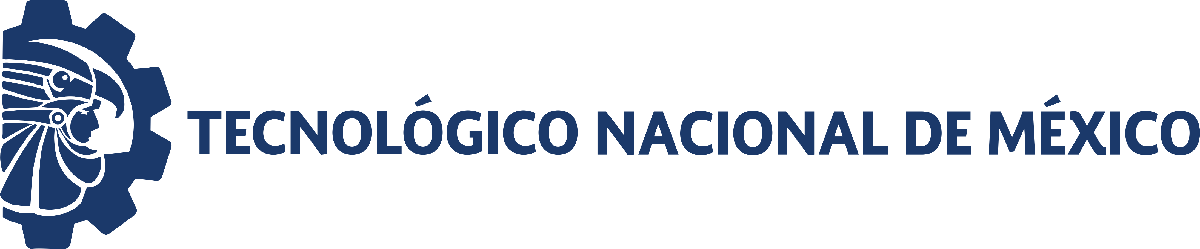                                 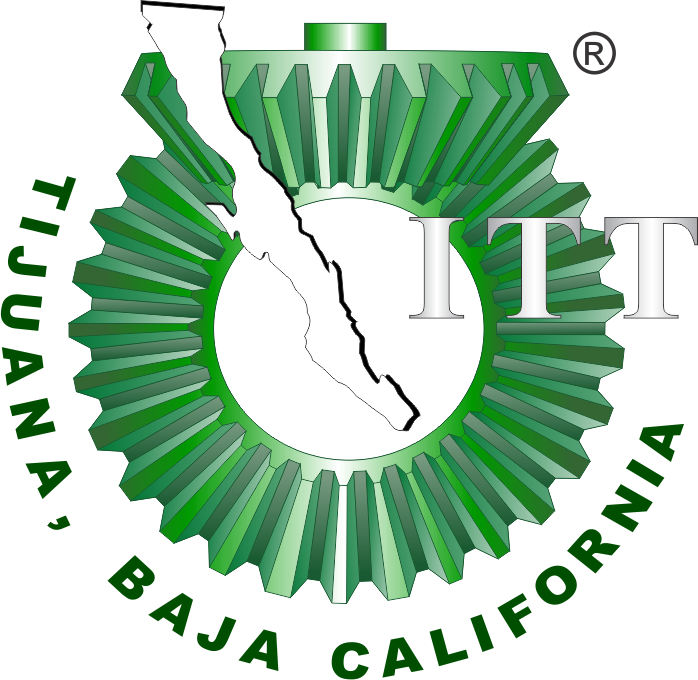

# Práctica 1: Leyes de crecimiento exponencial

**Departamento de Ingeniería Eléctrica y Electrónica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

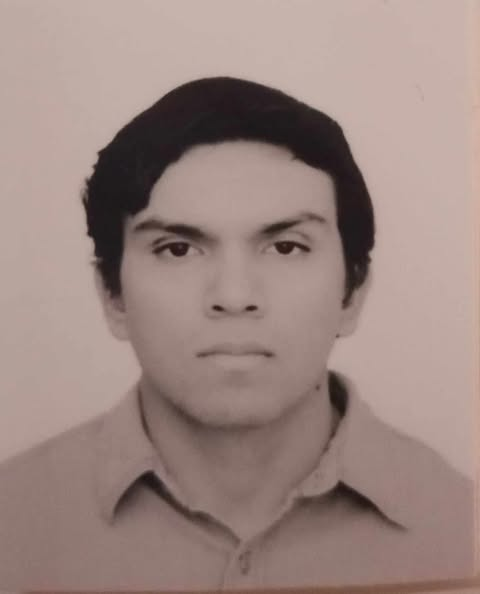

Nombre del alumno: **Chaparro Zamora Alain Yahir**

Número de control: **21212147**

Correo institucional: **l21212147@tectijuana.edu.mx**

**Carrera: Ingenieria Biomedica**

Asignatura: **Gemelos Digitales**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Simulation Data

clc; clear; close all; warning('off','all')


## Exponential growth


$$\dot{\dot{x} =\textrm{kx}}$$


dt = 0.5; %Integration step
x0 = 1; %Initial condition
k = 0.5; %Growth rate (parameter)
tend = 10; %Simulation final time

[t,x1,x2,x3] = sys_expgrowth(dt,x0,k,tend);

x1 =     1.0000
    1.2840
    1.6487
    2.1170
    2.7183
    3.4903
    4.4817
    5.7546
    7.3891
    9.4877


plotl1(t,x1,x2,x3)
function [t,x1,x2,x3] = sys_expgrowth(dt,x0,k,tend)
    t = (0:dt:tend)';
    n = round(tend/dt);
    x2 = zeros(numel(t),1); x2(1) = x0;
    x3 = zeros(numel(t),1); x3(1) = x0;



    %% Analytical solution
    x1 = x0*exp(k*t)


    %%Euler's method
    for i = 1:n
        x2(i+1) = x2(i) + (k*x2(i))*dt;
    end


    %%Heun's method
    for i = 1:n
        [fx3] = f(x3(i));
        x3n = x3(i) + fx3*dt;

        [fx3n] = f(x3n);
        x3(i+1) = x3(i) + (fx3 + fx3n)*dt/2;
    end


    function [dx3] = f(x3)
        dx3 = k*x3;
    end
end

function plotl1(t,x1,x2,x3)
    set (figure(1),'Color','w')
    set (gcf,'Units','Centimeters','Position',[2,2,20,10])
    set (gca,'FontName', 'Times New Roman')
    fontsize ( 10,'points')
picolors = [
    0.86, 0.1, 0.1;
    0.95, 0.62, 0.1; 
    0.60, 0.12, 0.6; 
];
    hold on; box on; grid off; colororder(picolors)

    plot(t,x1,'-','LineWidth',1)
    plot(t,x2,'--','LineWidth',1)
    plot(t,x3,':','LineWidth',2)
    xlabel('$t$ $[time]$','Interpreter','latex')
    ylabel('$x_i(t)$ $[units]$','Interpreter','latex')
    L=legend('$x_1(t):Analytical$','$x_2:Euler$','$x_3(t):Heun$');
    set(L,'Interpreter','Latex','Location','NorthEastOutside')
    title(L,'Exponential growth')
    xlim([0 10]); xticks(0:1:10)
    ylim([0 150]); yticks(0:25:150)
    exportgraphics(gcf,'Exponential_Growth.pdf','ContentType','vector')
end

## Exponential decay


$$\dot{\dot{x} =-\textrm{kx}}$$


Look for the point in the plot where x(t)= $\frac{X_0 }{2}$ (half-life), $t_{\frac{1}{2}}$) and compute the decay rate of the bioprocess, where k=$\frac{\textrm{ln2}}{t_{\frac{1}{2}} }$

dt = 0.01; %Integration step
x0 = 1; %Initial condition
k = 0.5; %Decay rate (parameter, now negative)
tend = 10; %Simulation final time

[t,x1,x2,x3] = sys_expdecay(dt,x0,-k,tend);
plotl2(t,x1,x2,x3)

function [t,x1,x2,x3] = sys_expdecay(dt,x0,k,tend)
    t = (0:dt:tend)';
    n = round(tend/dt);
    x2 = zeros(numel(t),1); x2(1) = x0;
    x3 = zeros(numel(t),1); x3(1) = x0;

    %% Analytical solution
    x1 = x0*exp(k*t);

    %% Euler's method
    for i = 1:n
        x2(i+1) = x2(i) + (k*x2(i))*dt;
    end

    %% Heun's method
    for i = 1:n
        [fx3] = f(x3(i));
        x3n = x3(i) + fx3*dt;

        [fx3n] = f(x3n);
        x3(i+1) = x3(i) + (fx3 + fx3n)*dt/2;
    end

    function [dx3] = f(x3)
        dx3 = k*x3;
    end
end

function plotl2(t,x1,x2,x3)
    set (figure(2),'Color','w')
    set (gcf,'Units','Centimeters','Position',[2,2,20,10])
    set (gca,'FontName', 'Times New Roman')
    fontsize ( 10,'points')
    picolors = [
        0.1, 0.1, 0.86;
        0.1, 0.62, 0.95; 
        0.12, 0.6, 0.12; 
    ];
    hold on; box on; grid off; colororder(picolors)

    plot(t,x1,'-','LineWidth',1)
    plot(t,x2,'--','LineWidth',1)
    plot(t,x3,':','LineWidth',2)
      xlabel('$t$ $[time]$','Interpreter','latex')
    ylabel('$x_i(t)$ $[units]$','Interpreter','latex')
    L=legend('$x_1(t):Analytical$','$x_2:Euler$','$x_3(t):Heun$');
    set(L,'Interpreter','Latex','Location','NorthEastOutside')
    title(L,'Exponential decay')
    xlim([0 10]); xticks(0:1:10)
    ylim([0 1]); yticks(0:0.1:1)
    exportgraphics(gcf,'Exponential_Decay.pdf','ContentType','vector')
end

## First-order pharmacycokinetics [modified exponential decay]: Controlled drug delivery by nanohydrogels


$$\dot{X=\beta \left(1-e^{-\textrm{kt}} \right)}$$


Reference: `González-Ayón, M. A., Sañudo-Barajas, J. A., Picos-Corrales, L. A., & Licea-Claverie, A. (2015). ``PNVCL-PEGMA nanohydrogels with tailored transition temperature for controlled delivery of 5-fluorouracil. Journal of Polymer Science Part A: Polymer Chemistry, 53(22), 2662–2672.`` doi:10.1002/pola.27766 `

clc; clear; close all;

sys = readmatrix('data.csv');
t = round(sys(:,1));
x1 = sys(:,2);
x2 = sys(:,3);
x3 = sys(:,4);
x4 = sys(:,5);

T = array2table([t, x1, x2, x3, x4], 'VariableNames', {'t_min', 'N32', 'N35', 'N36', 'N45'}); disp(T);

    t_min     N32      N35      N36      N45 
    _____    _____    _____    _____    _____

       0         0        0        0        0
      15     43.68    35.47    51.35    34.39
      30     64.31    55.89    69.07    49.08
      45      73.6    62.69    77.82    59.34
      60     80.95    70.15     84.3    68.31
      75     82.24    72.85     88.4    72.85
      91     85.59    75.44    92.07    76.74
     105      88.4    77.92    95.42    80.08
     120     90.56    78.03    97.15    83.65
     150     90.78    80.52    97.69    86.78
     180     90.24    80.73    97.69    88.83
     210      92.4     80.3    98.23    89.91



## Nonlinear regression and biostatics

rho = [0.1, 100];
mdl_x1 = pharmacokinetics(t,x1,rho); y1 = mdl_x1.Fitted; % Nanohydrogel N32


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value: 2.228
Adjusted R-squared: 0.9949
Corrected AIC (n/pars<40): 53.1970

    Parameter    Estimate       SE           MoE       CI95_Lower    CI95_Upper      pValue  
    _________    ________    _________    _________    __________    __________    __________

    {'k'   }     0.040504    0.0017568    0.0039143     0.036589      0.044418     5.3239e-10
    {'beta'}       89.847      0.82673       1.8421       88.004        91.689     1.0668e-16



mdl_x2 = pharmacokinetics(t,x2,rho); y2 = mdl_x2.Fitted; % Nanohydrogel N35 


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value: 2.228
Adjusted R-squared: 0.9963
Corrected AIC (n/pars<40): 46.5589

    Parameter    Estimate       SE           MoE       CI95_Lower    CI95_Upper      pValue  
    _________    ________    _________    _________    __________    __________    __________

    {'k'   }     0.037453    0.0013753    0.0030643     0.034388      0.040517     1.0315e-10
    {'beta'}       79.417      0.65053       1.4495       77.967        80.866     3.3367e-17



mdl_x3 = pharmacokinetics(t,x3,rho); y3 = mdl_x3.Fitted; % Nanohydrogel N36


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value: 2.228
Adjusted R-squared: 0.9876
Corrected AIC (n/pars<40): 65.0565

    Parameter    Estimate       SE           MoE       CI95_Lower    CI95_Upper      pValue  
    _________    ________    _________    _________    __________    __________    __________

    {'k'   }     0.041963    0.0028129    0.0062676     0.035695      0.04823       3.686e-08
    {'beta'}       95.959       1.3342       2.9728       92.986       98.932      6.5864e-15



mdl_x4 = pharmacokinetics(t,x4,rho); y4 = mdl_x4.Fitted; % Nanohydrogel N45


Sample size (n): 12
Parameters to be estimated (pars): 2
Degrees of freedom: 10
Significance level (alpha): 0.05
t-Student value: 2.228
Adjusted R-squared: 0.9903
Corrected AIC (n/pars<40): 60.4553

    Parameter    Estimate       SE           MoE       CI95_Lower    CI95_Upper      pValue  
    _________    ________    _________    _________    __________    __________    __________

    {'k'   }     0.025988    0.0015189    0.0033843     0.022604      0.029373     9.8118e-09
    {'beta'}       87.728       1.4513       3.2337       84.494        90.962     3.7311e-14



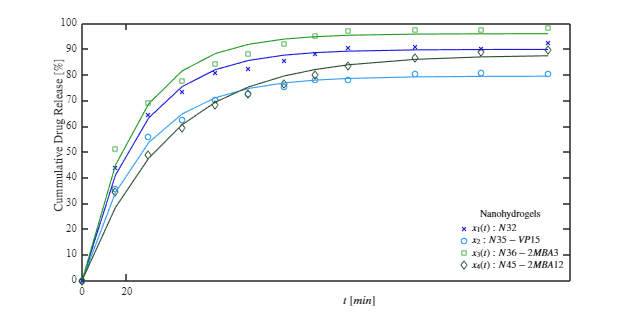

plotdata(t,x1,x2,x3,x4,y1,y2,y3,y4)

## Functions

function mdl = pharmacokinetics(to, xo, rho)

    function xi = model(rho, t)
        k = rho(1);
        beta = rho(2);
        xi = beta * (1 - exp(-k * t));
    end

    mdl = fitnlm(to, xo, @model, rho);

    Estimate = table2array(mdl.Coefficients(:,1));
    SE = table2array(mdl.Coefficients(:,2));
    pvalue = table2array(mdl.Coefficients(:,4));

    alpha = 0.05;
    CI95 = coefCI(mdl, alpha);

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


x =          0
    2.9994
    5.9977
    8.9948
   11.9908
   14.9856
   17.9792
   20.9717
   23.9631
   26.9533


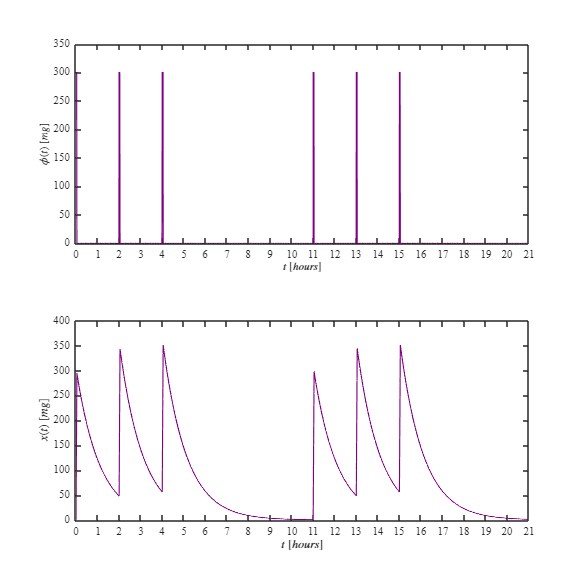

    dof = mdl.DFE; % Grados de libertad

t =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900


x =          0
    2.9861
    5.9448
    8.8763
   11.7807
   14.6585
   17.5098
   20.3348
   23.1339
   25.9072


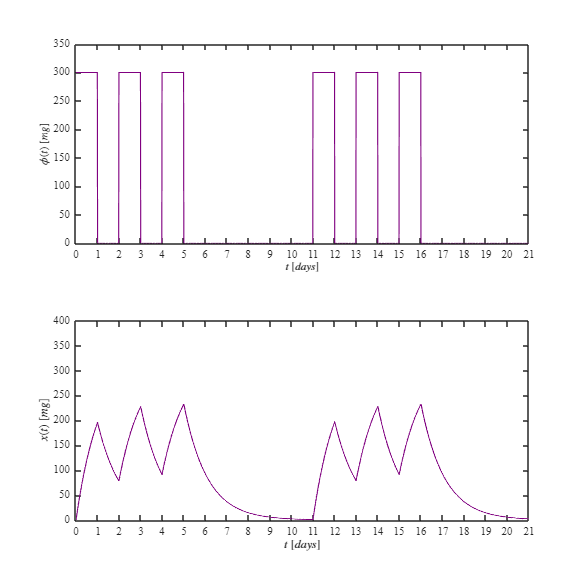

    tval = tinv(1 - alpha/2, dof); % Valor t de Student
    MoE = SE * tval; % Margen de error

    Parameters = {'k'; 'beta'};  
    Results = table(Parameters, Estimate, SE, MoE, CI95(:,1), CI95(:,2), pvalue, ...
                    'VariableNames', {'Parameter', 'Estimate', 'SE', 'MoE', 'CI95_Lower', 'CI95_Upper', 'pValue'});

    fprintf('\nSample size (n): %d', numel(xo));
    fprintf('\nParameters to be estimated (pars): %d', numel(rho));
    fprintf('\nDegrees of freedom: %d', dof);
    fprintf('\nSignificance level (alpha): %.2f', alpha);
    fprintf('\nt-Student value: %.3f', tval);
    fprintf('\nAdjusted R-squared: %.4f', mdl.Rsquared.Adjusted);
    fprintf('\nCorrected AIC (n/pars<40): %.4f\n\n', mdl.ModelCriterion.AICc);

    disp(Results);
end


function plotdata(t,x1,x2,x3,x4,y1,y2,y3,y4)
    
      set (figure(3),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,10])
    set(gca,'FontName','Times New Roman')
    fontsize ( 10,'points')
    picolors = [
        0.1, 0.1, 0.86;
        0.2, 0.62, 0.95; 
        0.12, 0.6, 0.12; 
        0.18, 0.3, 0.2; 
    ];
   % shuffledcolors = picolors(randperm(size(picolors,1)),:);
    hold on; box on; grid off; colororder(picolors)
    %ExperimentalData
    plot(t,x1,'x','MarkerSize',5,'LineWidth',1)
    plot(t,x2,'o','MarkerSize',5,'LineWidth',1)
    plot(t,x3,'square','MarkerSize',5,'LineWidth',1)
    plot(t,x4,'diamond','MarkerSize',5,'LineWidth',1)
    %FittedData
    plot(t,y1,'-','LineWidth',1)
    plot(t,y2,'-','LineWidth',1)
    plot(t,y3,'-','LineWidth',1)
    plot(t,y4,'-','LineWidth',1)
    %Legends
    xlabel('$t$ $[min]$','Interpreter','latex')
    ylabel('Cummulative Drug Release $[\%]$','Interpreter','latex')
    xlim([0 220]); xticks(0:20:20)
    ylim([0 100]); yticks(0:10:100)
    L=legend('$x_1(t):N32$','$x_2:N35-VP15$','$x_3(t):N36-2MBA3$','$x_4(t):N45-2MBA12$');
    set(L,'Interpreter','Latex','Location','SouthEast','Box','Off')
    title(L,'Nanohydrogels')
    
    exportgraphics(gcf,'Nanohydrogels.pdf','ContentType','vector')
    exportgraphics(gcf,'Nanohydrogels.png','Resolution','800')
    exportgraphics(gcf,'Nanohydrogels.jpg','Resolution','800')
    print('Nanohydrogels','-dsvg')
    print('Nanohydrogels','-depsc')
end

## Chemotherapy dynamics in the blood compartment

Assume that the chemotherapy drug within the blood compartment follows a first-order kinetics. Let us apply the modified exponential decay to illustrate the dynamics of this drug when administered withthe following scheme: 

- **Protocol:** (3 Imatinib intakes every 2 days + 7 days of rest)* 2 cycles.

- **Dosing:** 300 mg/day per dose.

- **Application frequency: **One dose every 2 days.

- **Doses per cycle: **3 doses.

- **Number of cycles: **2 cycles.

- **Imatinib biological half-life:** $\left\lbrack t_{\frac{1}{2}} \right\rbrack$: 18 hours [0.75 days]. https://go.drugbank.com/drugs/DB00619

- **ODE: **$\dot{x} =\phi \left(t\right)-$$\mu x$

clc; clear; close all; warning('off','all')

### Time: Hours


dt = 0.01; dose = 300; mu = log(2)/18 ; tend = 21*24;
phi = zeros (tend/dt+1,1);
%Cycle1
phi(1:1/dt) = dose;
phi(2*24/dt:(2*24+1)/dt) = dose;
phi(4*24/dt:(4*24+1)/dt) = dose;

% Cycle 2
phi(11*24/dt:(11*24+1)/dt) = dose;
phi(13*24/dt:(13*24+1)/dt) = dose;
phi(15*24/dt:(15*24+1)/dt) = dose;

[t,x] = sys_chemo(dt,mu,phi,tend)
plotchemo(t/24,phi,x,'hours')



### Time : Days

dt = 0.01; dose = 300; mu = log(2)/(18/24) ; tend = 24;
phi = zeros (tend/dt+1,1);

%Cycle1
phi(1:1/dt) = dose;
phi(2/dt:3/dt) = dose;
phi(4/dt:5/dt) = dose;

%Cycle1
phi(11/dt:12/dt) = dose;
phi(13/dt:14/dt) = dose;
phi(15/dt:16/dt) = dose;

[t,x] = sys_chemo(dt,mu,phi,tend)
plotchemo(t,phi,x,'days')

### Functions

function [t,x] = sys_chemo(dt,mu,phi,tend)
    t = (0:dt:tend)';
    n = round(tend/dt);
    x = zeros (numel(t),1);

    %Heun's method
    for i = 1:n
       [fx] = f(x(i),phi(i));
       xn = x(i) + fx*dt;
       [fxn] = f(xn,phi(i));

       x(i+1) = x(i) + (fx + fxn)*dt/2;
    end
    function [dx] = f(x,phi)
       dx = phi - mu*x;
    end
end


function plotchemo(t,phi,x,time)
set (figure(),'Color','w')
    set(gcf,'Units','Centimeters','Position',[2,2,20,20])

    subplot(2,1,1)
    set(gca,'FontName','Times New Roman')
    fontsize ( 10,'points')
 %   picolors = [0.1, 0.1, 0.86;0.2, 0.62, 0.95; 0.12, 0.6, 0.12; 0.18, 0.3, 0.2];
 hold on; box on; grid off; 
   plot(t,phi,'-','LineWidth',1,'Color',[0.5,0.0,0.5])
   %Legends
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$\phi(t)$ $[mg]$','Interpreter','latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 350]); yticks(0:50:350)

     subplot(2,1,2)

    set(gca,'FontName','Times New Roman')
    fontsize ( 10,'points')
 %   picolors = [0.1, 0.1, 0.86;0.2, 0.62, 0.95; 0.12, 0.6, 0.12; 0.18, 0.3, 0.2];
 hold on; box on; grid off; 
   plot(t,x,'-','LineWidth',1,'Color',[0.5,0.0,0.5])
   %Legends
    xlabel('$t$ $[days]$','Interpreter','latex')
    ylabel('$x(t)$ $[mg]$','Interpreter','latex')
    xlim([0 21]); xticks(0:1:21)
    ylim([0 400]); yticks(0:50:400)


  exportgraphics(gcf,['Chemo',time,' .pdf'],'ContentType','vector')
end